syms  ms k g kp cp c w mu

ms=250; % [kg]
k=25000; % [N/m] suspension stiffness
g=9.81; %  [m/s^2]

% tire
% mns=3344.31; % [kg]
mns=25; % [kg]

kp=100000; % [N/m]
cp=0;  % [Ns/m]
c=2150;
mu=ms/mns;
% c=sqrt(kp*mns)*sqrt(3*mu^3/(2*(1+mu^3)))

M=[ms      0
    0     mns];

M =    250     0
     0    25




C=[c      -c;
    -c     c+cp];

C =         2150       -2150
       -2150        2150




K=[k      -k
    -k     k+kp];

K =        25000      -25000
      -25000      125000



Kdynamic=-w^2*M+K+1i*w*C;
H=inv(Kdynamic)

$$H = \begin{array}{l} \left(\begin{array}{cc} \frac{-w^{2}+86\,w\,\mathrm{i}+5000}{50\,\left(5\,w^{4}-473\,w^{3}\,\mathrm{i}-25500\,w^{2}+172000\,w\,\mathrm{i}+2000000\right)} & \sigma_{1}\\ \sigma_{1} & \frac{-5\,w^{2}+43\,w\,\mathrm{i}+500}{25\,\left(5\,w^{4}-473\,w^{3}\,\mathrm{i}-25500\,w^{2}+172000\,w\,\mathrm{i}+2000000\right)} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\frac{43\,w-500\,\mathrm{i}}{25\,\left(5\,w^{4}\,\mathrm{i}+473\,w^{3}-25500\,w^{2}\,\mathrm{i}-172000\,w+2000000\,\mathrm{i}\right)} \end{array}$$

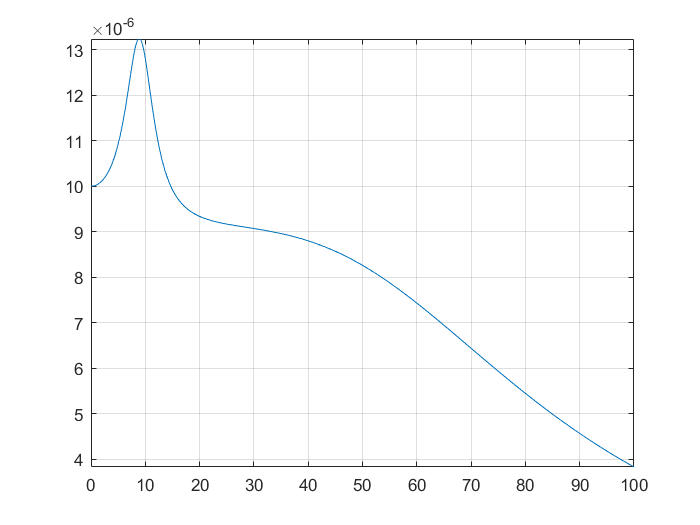


assume(w,'positive')
fplot(abs(H(2,2)),[0 100])

grid on